# Platform path finding using RRT

## 2D grid

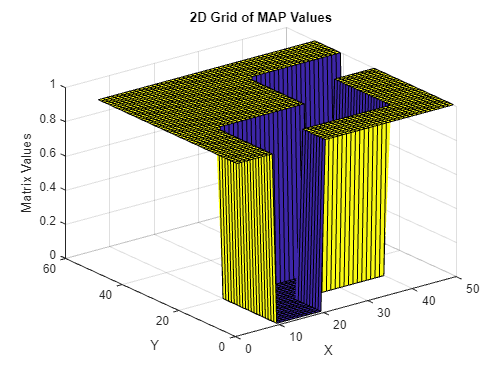

grid = ones(50,50);

% Obstacles
grid(10:20,1:20) = 0;
grid(20:40, 10:20) = 0;
grid(30:40, 20:40) = 0;
grid(40:50, 30:40) = 0;

% Create a 2D grid using meshgrid
[X, Y] = meshgrid(1:50, 1:50);

% Plot the 2D grid with the matrix values
figure
surf(Y, X, grid)
xlabel('X')
ylabel('Y')
zlabel('Matrix Values')
title('2D Grid of MAP Values')

## Path

goal_node = [45,35];
start_node = [15,15];

[rrt_path, tree] = RRT2D(grid, start_node, goal_node);

Output argument "obstacleDetected" (and possibly others) not assigned a value
in the execution with "RRT2D>checkObstacleIntersection" function.

Error in RRT2D (line 53)
        intersects = checkObstacleIntersection(grid, tree(index, 2:3), new_node);

% Plot the 2D grid with the matrix values
figure
surf(Y, X, grid)
xlabel('X')
ylabel('Y')
zlabel('Matrix Values')
title('2D Grid of MAP Values')
hold on 
scatter3(rrt_path(:,1), rrt_path(:,2), zeros(size(rrt_path(:,1))), 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'red');
